# nb20230803_153943_sharptrack2paxinos_coronal.mlx

## 0 Place a mark at the optic fiber tip

addpath('\\ettina\Magill_Lab\Kouichi Nakamura\Analysis\allenCCFdata')
cd('\\ettina\Magill_Lab\Kouichi Nakamura\Analysis\Images from Otto\20230406 kms058') %TODO

subject_id = 'Paxinos_sagittal' %TODO

subject_id = 'Paxinos_sagittal'


% * remember to run one cell at a time, instead of the whole script at once *

% directory of histology images
image_folder = '\\ettina\Magill_Lab\Kouichi Nakamura\Analysis\Images from Otto\20230406 kms058\Paxinos coronal';  %TODO


% directory to save the processed images -- can be the same as the above image_folder
% results will be put inside a new folder called 'processed' inside of this image_folder
save_folder = image_folder;

% name of images, in order anterior to posterior or vice versa
% once these are downsampled they will be named ['original name' '_processed.tif']
image_file_names = dirregexp(image_folder, '.+\_dots\.tif$'); % get the contents of the image_folder
image_file_names = natsortfiles({image_file_names.name});


disp(image_file_names')

    {'1_dots.tif'}
    {'2_dots.tif'}
    {'3_dots.tif'}
    {'4_dots.tif'}
    {'5_dots.tif'}
    {'6_dots.tif'}



% image_file_names = {'slide no 2_RGB.tif','slide no 3_RGB.tif','slide no 4_RGB.tif'}; % alternatively, list each image in order

% if the images are individual slices (as opposed to images of multiple
% slices, which must be cropped using the cell CROP AND SAVE SLICES)
image_files_are_individual_slices = true;

% use images that are already at reference atlas resolution (here, 10um/pixel)
use_already_downsampled_image = false; %TODO

% pixel size parameters: microns_per_pixel of large images in the image
% folder (if use_already_downsampled_images is set to false);
% microns_per_pixel_after_downsampling should typically be set to 10 to match the atlas
microns_per_pixel = 4.5843 ; %TODO 
microns_per_pixel_after_downsampling = 10 ;%TODO



% ----------------------
% additional parameters
% ----------------------

% if the images are cropped (image_file_are_individual_slices = false),
% name to save cropped slices as; e.g. the third cropped slice from the 2nd
% image containing many slices will be saved as: save_folder/processed/save_file_name02_003.tif
save_file_name = [subject_id,'_'];

% increase gain if for some reason the images are not bright enough
gain = 1; 

% plane to view ('coronal', 'sagittal', 'transverse')
plane = 'coronal'; %TODO

% size in pixels of reference atlas brain. For coronal slice, this is 800 x 1140
if strcmp(plane,'coronal')
    atlas_reference_size = [800 1140]; 
elseif strcmp(plane,'sagittal')
    atlas_reference_size = [800 1320]; 
elseif strcmp(plane,'transverse')
    atlas_reference_size = [1140 1320];
end






% finds or creates a folder location for processed images -- 
% a folder within save_folder called processed
folder_processed_images = fullfile(save_folder, 'processed');
if ~exist(folder_processed_images)
    mkdir(folder_processed_images)
end


% directory of histology
processed_images_folder = folder_processed_images; %TODO

% name the saved probe points, to avoid overwriting another set of probes going in the same folder
probe_save_name_suffix = '_paxinos'; %TODO

% directory of reference atlas files
annotation_volume_location = "\\ettina\Magill_lab\Kouichi Nakamura\Analysis\allenCCFdata\annotation_volume_10um_by_index.npy";
structure_tree_location = "\\ettina\Magill_lab\Kouichi Nakamura\Analysis\allenCCFdata\structure_tree_safe_2017.csv";
template_volume_location = "\\ettina\Magill_lab\Kouichi Nakamura\Analysis\allenCCFdata\template_volume_10um.npy";

% plane to view ('coronal', 'sagittal', 'transverse')
% plane = 'sagittal';


% load the reference brain and region annotations
if ~exist('av','var') || ~exist('st','var') || ~exist('tv','var')
    disp('loading reference atlas...')
    av = readNPY(annotation_volume_location);
    st = loadStructureTree(structure_tree_location);
    tv = readNPY(template_volume_location);
end

% select the plane for the viewer
if strcmp(plane,'coronal')
    av_plot = av;
    tv_plot = tv;
elseif strcmp(plane,'sagittal')
    av_plot = permute(av,[3 2 1]);
    tv_plot = permute(tv,[3 2 1]);
elseif strcmp(plane,'transverse')
    av_plot = permute(av,[2 3 1]);
    tv_plot = permute(tv,[2 3 1]);
end

[https://github.com/cortex-lab/allenCCF/issues/70](https://github.com/cortex-lab/allenCCF/issues/70)

**affine transform result is very much skewed depending on the size of images used**

## 1. ENTER PARAMETERS AND FILE LOCATION

% subject_id = 'kms058' %TODO

% file location of object points
% save_folder = '\\ettin\Magill_Lab\Kouichi Nakamura\Analysis\Images from Otto\20230406 kms058\RGB2\processed'


% directory of reference atlas files
% annotation_volume_location = "\\ettin\Magill_lab\Kouichi Nakamura\Analysis\allenCCFdata\annotation_volume_10um_by_index.npy";
% structure_tree_location = "\\ettin\Magill_lab\Kouichi Nakamura\Analysis\allenCCFdata\structure_tree_safe_2017.csv";

% name of the saved object points
object_save_name_suffix = probe_save_name_suffix;% [subject_id,'_opticfiber_'];

% either set to 'all' or a list of indices from the clicked objects in this file, e.g. [2,3]
objects_to_analyze = 'all';

% plane used to view when points were clicked ('coronal' -- most common, 'sagittal', 'transverse')
% plane = 'sagittal';

% brain figure black or white
black_brain = true;


## 2. LOAD THE REFERENCE ANNOTATIONS AND PROBE POINTS


% load the reference brain annotations
if ~exist('av','var') || ~exist('st','var')
    disp('loading reference atlas...')
    av = readNPY(annotation_volume_location);
    st = loadStructureTree(structure_tree_location);
end


% load object points
objectPoints = load(fullfile(save_folder, 'processed',['probe_points' object_save_name_suffix]));

% determine which objects to analyze
if strcmp(objects_to_analyze,'all')
    objects = 1:size(objectPoints.pointList.pointList,1);
else
    objects = objects_to_analyze;
end 

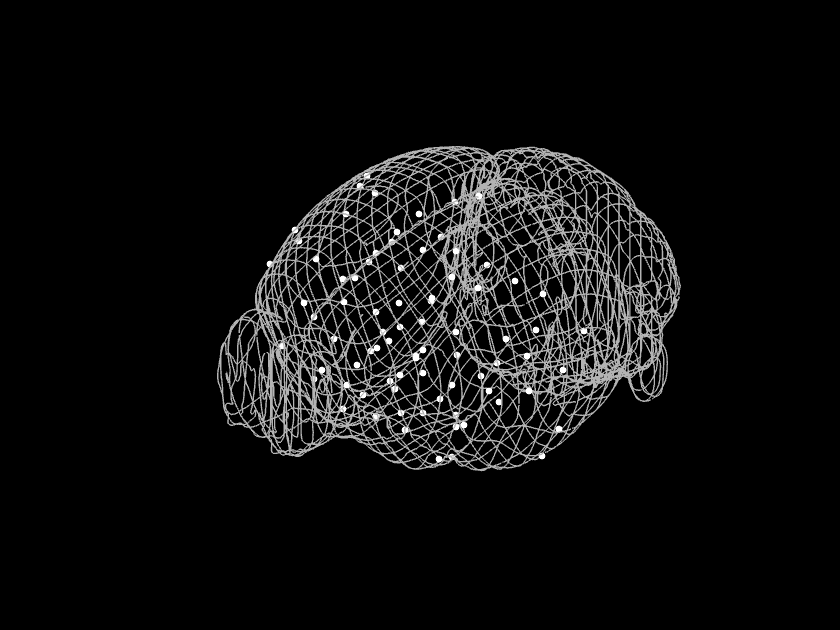

Clicked points for object 1


                             name                                 acronym         AP_location    DV_location    ML_location    avIndex 
    ______________________________________________________    ________________    ___________    ___________    ___________    ________

    {'root'                                              }    {'root'        }        1.95          2.78           -3.37       {[   1]}
    {'Piriform area'                                     }    {'PIR'         }        1.95          5.36           -2.85       {[ 417]}
    {'Secondary motor area layer 6a'                     }    {'MOs6a'       }        1.95          3.28           -1.57       {[  29]}
    {'Anterior olfactory nucleus'                        }    {'AON'         }        1.95          5.12           

%% BRING UP THE RELEVANT DATA FOR EACH PROBE POINTS, FOR FURTHER ANALYSIS

% initialize cell array containing info on each clicked point
if length(objects) > 1
    roi_annotation = cell(length(objects),1);
    roi_location = cell(length(objects),1);
end

% generate needed values
bregma = allenCCFbregma(); % bregma position in reference data space
atlas_resolution = 0.010; % mm

% plot brain grid
ProbeColors = [1 1 1; 1 .75 0;  .3 1 1; .4 .6 .2; 1 .35 .65; .7 .7 1; .65 .4 .25; .7 .95 .3; .7 0 0; .6 0 .7; 1 .6 0]; 
% order of colors: {'white','gold','turquoise','fern','bubble gum','overcast sky','rawhide', 'green apple','purple','orange','red'};
fwireframe = plotBrainGrid([], [], [], black_brain); hold on; 
fwireframe.InvertHardcopy = 'off';



for object_num = objects
    
    selected_object = objects(object_num);
        
    % get the object points for the currently analyzed object    
    if strcmp(plane,'coronal')
        curr_objectPoints = objectPoints.pointList.pointList{selected_object,1}(:, [3 2 1]);
    elseif strcmp(plane,'sagittal')
        curr_objectPoints = objectPoints.pointList.pointList{selected_object,1}(:, [1 2 3]);
    elseif strcmp(plane,'transverse')
        curr_objectPoints = objectPoints.pointList.pointList{selected_object,1}(:, [1 3 2]);
    end

    % plot points on the wire frame brain
    figure(fwireframe); hold on
    hp = plot3(curr_objectPoints(:,1), curr_objectPoints(:,3), curr_objectPoints(:,2), '.','linewidth',2, 'color',[ProbeColors(object_num,:) .2],'markers',10);   

    % use the point's position in the atlas to get the AP, DV, and ML coordinates
    ap = -(curr_objectPoints(:,1)-bregma(1))*atlas_resolution;
    dv = (curr_objectPoints(:,2)-bregma(2))*atlas_resolution;
    ml = (curr_objectPoints(:,3)-bregma(3))*atlas_resolution;

    roi_location_curr = [ap dv ml];
    
    % initialize array of region annotations
    roi_annotation_curr = cell(size(curr_objectPoints,1),3);    
    
    % loop through every point to get ROI locations and region annotations
    for point = 1:size(curr_objectPoints,1)

        % find the annotation, name, and acronym of the current ROI pixel
        ann = av(curr_objectPoints(point,1),curr_objectPoints(point,2),curr_objectPoints(point,3));
        name = st.safe_name{ann};
        acr = st.acronym{ann};

        roi_annotation_curr{point,1} = ann;
        roi_annotation_curr{point,2} = name;
        roi_annotation_curr{point,3} = acr;

    end
    
    % save results in cell array
    if length(objects) > 1
        roi_annotation{object_num} = roi_annotation_curr;
        roi_location{object_num} = roi_location_curr;
    else
        roi_annotation = roi_annotation_curr;
        roi_location = roi_location_curr;
    end
 
    % display results in a table
    disp(['Clicked points for object ' num2str(selected_object)])
    roi_table = table(roi_annotation_curr(:,2),roi_annotation_curr(:,3), ...
                        roi_location_curr(:,1),roi_location_curr(:,2),roi_location_curr(:,3), roi_annotation_curr(:,1), ...
         'VariableNames', {'name', 'acronym', 'AP_location', 'DV_location', 'ML_location', 'avIndex'});
     disp(roi_table)
    
end



% now, use roi_location and roi_annotation for your further analyses

## Prepare coordinates from Paxinos

vns = { 'VariableNames', {'AP_location','DV_location','ML_location', 'figure'}};

% AP, DV, ML (left to right), slice
mat_PaFr = [...
    1.97, 1.8828, -2.7045, 14;...
    1.97, 4.0761, -2.4465, 14;...
    1.97, 2.2223, -1.2349, 14;...
    1.97, 3.8385, -0.8031, 14;...
    1.97, 0.9414, -0.0032, 14;...
    1.97, 4.6330, -0.0130, 14;...
    1.97, 3.838, 0.854, 14;...
    1.97, 2.229, 1.546, 14;...
    1.97, 3.838, 2.511, 14;...
    1.97, 1.693, 2.823, 14;...
    0.97, 1.690, -3.192, 23;...
    0.97, 3.828, -2.537, 23;...
    0.97, 5.503, -2.557, 23;...
    0.97, 1.870, -0.879, 23;...
    0.97, 4.285, -0.779, 23;...
    0.97, 0.898, -0.013, 23;...
    0.97, 2.527, -0.013, 23;...
    0.97, 5.348, -0.013, 23;...
    0.97, 1.909, 0.807, 23;...
    0.97, 4.285, 0.757, 23;...
    0.97, 3.648, 2.454, 23;...
    0.97, 5.348, 2.454, 23;...
    0.97, 1.632, 3.158, 23;...
    0.01, 2.554, -4.071, 31;...
    0.01, 4.870, -2.687, 31;...
    0.01, 5.958, -2.192, 31;...
    0.01, 2.039, -1.380, 31;...
    0.01, 3.749, -0.710, 31;...
    0.01, 0.800, 0.011, 31;...
    0.01, 4.606, -0.013, 31;...
    0.01, 5.643, 0.011, 31;...
    0.01, 3.698, 0.707, 31;...
    0.01, 2.104, 1.229, 31;...
    0.01, 5.804, 2.290, 31;...
    0.01, 4.748, 2.787, 31;...
    0.01, 2.677, 4.140, 31;...
    -0.95, 3.300, -4.358, 39;...
    -0.95, 4.071, -3.206, 39;...
    -0.95, 0.768, -2.608, 39;...
    -0.95, 1.618, -1.269, 39;...
    -0.95, 4.416, -1.219, 39;...
    -0.95, 5.526, -1.430, 39;...
    -0.95, 0.588, -0.002, 39;...
    -0.95, 3.239, -0.013, 39;...
    -0.95, 4.618, -0.006, 39;...
    -0.95, 5.753, -0.013, 39;...
    -0.95, 1.675, 1.087, 39;...
    -0.95, 4.312, 1.369, 39;...
    -0.95, 5.403, 1.419, 39;...
    -0.95, 0.804, 2.298, 39;...
    -0.95, 3.999, 3.166, 39;...
    -0.95, 3.350, 4.261, 39;...
    -2.03, 2.961, -4.493, 48;...
    -2.03, 1.264, -3.711, 48;...
    -2.03, 5.631, -3.463, 48;...
    -2.03, 3.194, -2.148, 48;...
    -2.03, 4.851, -1.349, 48;...
    -2.03, 0.397, -0.012, 48;...
    -2.03, 1.740, 0, 48;...
    -2.03, 4.497, -0.013, 48;...
    -2.03, 5.981, -0.005, 48;...
    -2.03, 4.917, 1.325, 48;...
    -2.03, 3.194, 2.217, 48;...
    -2.03, 1.364, 3.660, 48;...
    -2.03, 5.881, 3.419, 48;...
    -2.03, 2.789, 4.443, 48;...%TODO
    -3.07, 2.522, -4.340, 56;...
    -3.07, 5.509, -3.200, 56;...
    -3.07, 3.308, -2.331, 56;...
    -3.07, 4.155, -1.907, 56;...
    -3.07, 2.362, -1.479, 56;...
    -3.07, 0.674, -0.042, 56;...
    -3.07, 3.178, 0.003, 56;...
    -3.07, 5.459, 0.038, 56;...
    -3.07, 2.422, 1.587, 56;...
    -3.07, 4.155, 1.986, 56;...
    -3.07, 3.078, 2.365, 56;...
    -3.07, 5.509, 3.340, 56;...
    -3.07, 2.362, 4.319, 56;...%TODO
    ]

mat_PaFr =     1.9700    1.8828   -2.7045   14.0000
    1.9700    4.0761   -2.4465   14.0000
    1.9700    2.2223   -1.2349   14.0000
    1.9700    3.8385   -0.8031   14.0000
    1.9700    0.9414   -0.0032   14.0000
    1.9700    4.6330   -0.0130   14.0000
    1.9700    3.8380    0.8540   14.0000
    1.9700    2.2290    1.5460   14.0000
    1.9700    3.8380    2.5110   14.0000
    1.9700    1.6930    2.8230   14.0000



PaFr = array2table(mat_PaFr, vns{:});

PaFr.AP_location = PaFr.AP_location * -1;


## DV

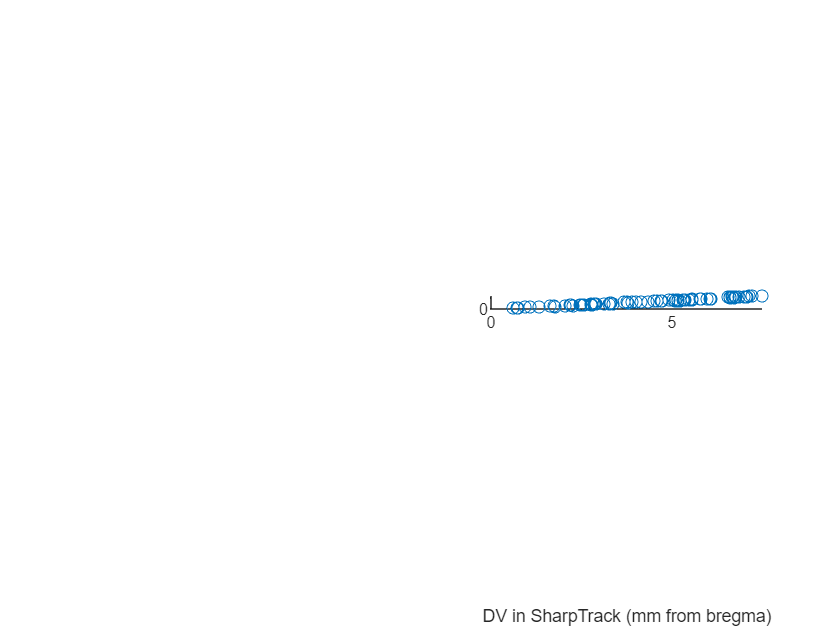

figure
ax = axes;
plot(roi_table.DV_location, PaFr.DV_location, 'o')
box off;
tickdir out;
xlabel('DV in SharpTrack (mm from bregma)')
ylabel('DV in Paxinos (mm from bregma)')

% figure
% ax = axes;
% hold on
% for i = 1:79
%     text(roi_table.DV_location(i), PaFr.DV_location(i), string(i));
% end
% box off;
% tickdir out;
% xlabel('DV in SharpTrack (mm from bregma)')
% ylabel('DV in Paxinos (mm from bregma)')
% 
% xlim([0 8])
% ylim([0 6])

5

21

66

79


X = [ones(size(roi_table.DV_location)) , roi_table.DV_location];
Y = PaFr.DV_location;
b_DV = X\Y

b_DV =    -0.1306
    0.8250


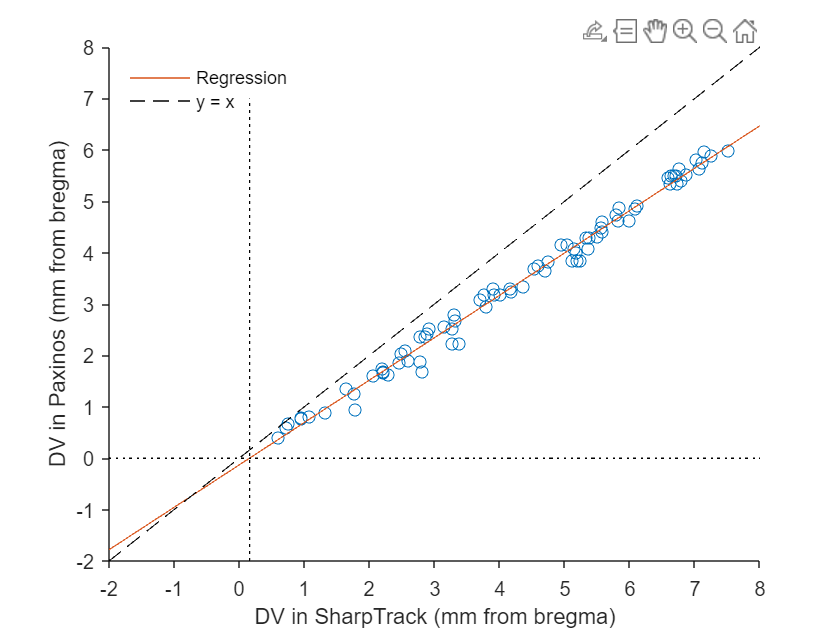


x = -2:0.01:8; % 10 micron
y = b_DV(1) + b_DV(2) * x;

hold on
ax.XTick = -2:8;
L1 = plot(x, y, DisplayName='Regression');
plot(xlim, [0 0], 'k:')
plot([x(find(y >=0,1,"first")), x(find(y >=0,1,"first"))], ylim, 'k:')

L2 = plot(x, x, 'k--',  DisplayName='y = x');

legend([L1 L2], Location="northwest", Box ='off');

fprintf("At y = 0, i.e. the real bregma, SharpTrack DV value is %.3f mm\n", x(find(y >=0,1,"first")));

At y = 0, i.e. the real bregma, SharpTrack DV value is 0.160 mm


fprintf("SharpTrack depth x can be converted to Paxinos depth by y = %.3f * x %+.3f\n", b_DV(2), b_DV(1));

SharpTrack depth x can be converted to Paxinos depth by y = 0.825 * x -0.131


## AP

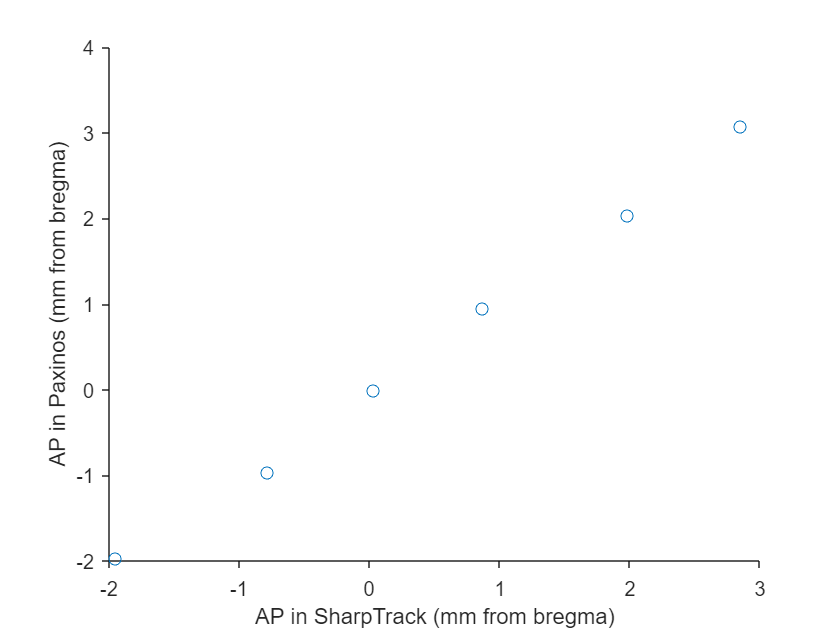

figure
ax = axes;
plot(roi_table.AP_location * -1, PaFr.AP_location, 'o')
box off;
tickdir out;
xlabel('AP in SharpTrack (mm from bregma)')
ylabel('AP in Paxinos (mm from bregma)')


X = [ones(size(roi_table.AP_location)) , roi_table.AP_location * -1];
Y = PaFr.AP_location;
b_AP = X\Y

b_AP =    -0.0189
    1.0635



x = -6:0.01:5; % 10 micron
y = b_AP(1) + b_AP(2) * x;

hold on
L1 = plot(x, y, DisplayName='Regression');

plot(xlim, [0 0], 'k:')
plot([x(find(y >=0,1,"first")), x(find(y >=0,1,"first"))], ylim, 'k:')

L2 = plot(x, x, 'k--',  DisplayName='y = x');
legend([L1 L2], Location="northwest", Box ='off');

fprintf("At y = 0, i.e. the real bregma, SharpTrack AP value is %.3f mm\n", x(find(y >=0,1,"first")));

At y = 0, i.e. the real bregma, SharpTrack AP value is 0.020 mm


fprintf("SharpTrack AP x can be converted to Paxinos AP by y = %.3f * x %+.3f\n", b_AP(2), b_AP(1));

SharpTrack AP x can be converted to Paxinos AP by y = 1.064 * x -0.019


## ML

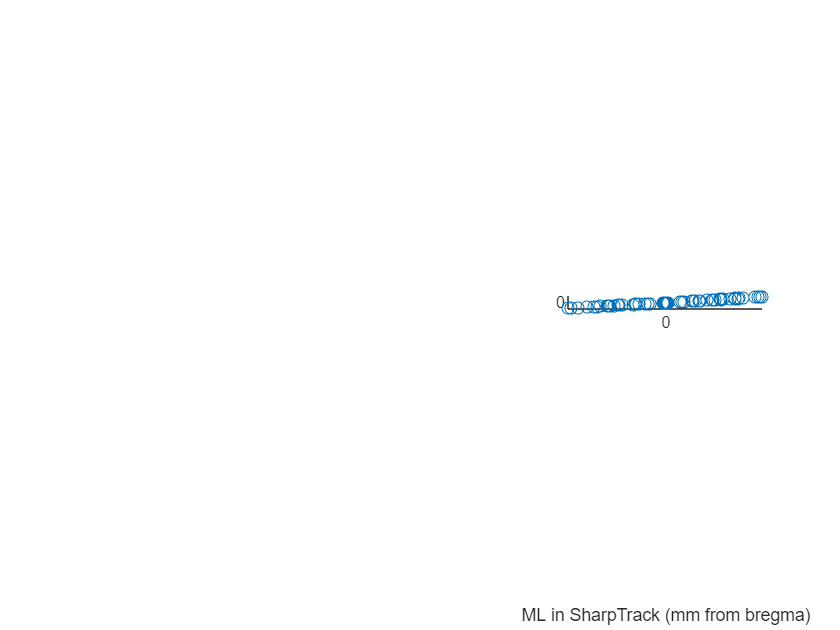

figure
ax = axes;
plot(roi_table.ML_location, PaFr.ML_location, 'o')
box off;
tickdir out;
xlabel('ML in SharpTrack (mm from bregma)')
ylabel('ML in Paxinos (mm from bregma)')


X = [ones(size(roi_table.ML_location)) , roi_table.ML_location];
Y = PaFr.ML_location;
b_ML = X\Y

b_ML =    -0.0022
    0.8846


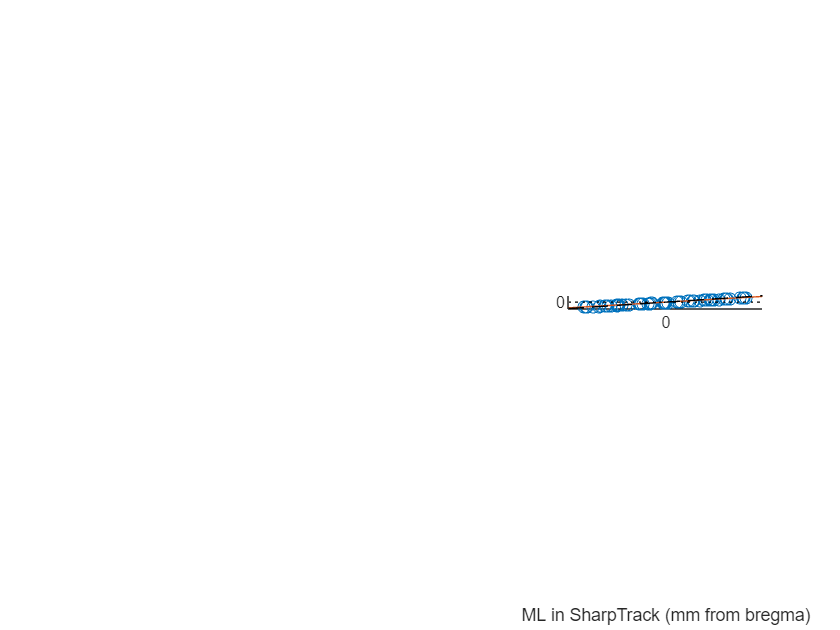


x = -6:0.01:6; % 10 micron
y = b_ML(1) + b_ML(2) * x;

hold on
L1 = plot(x, y, DisplayName='Regression');

plot(xlim, [0 0], 'k:')
% plot([x(find(y >=0,1,"first")), x(find(y >=0,1,"first"))], ylim, 'k:')

L2 = plot(x, x, 'k--',  DisplayName='y = x');
legend([L1 L2], Location="northeast", Box ='off');

fprintf("At y = 0, i.e. the real bregma, SharpTrack ML value is %.3f mm\n", x(find(y >=0,1,"first")));

At y = 0, i.e. the real bregma, SharpTrack ML value is 0.010 mm


fprintf("SharpTrack ML x can be converted to Paxinos ML by y = %.3f * x %+.3f\n", b_ML(2), b_ML(1));

SharpTrack ML x can be converted to Paxinos ML by y = 0.885 * x -0.002
